summary_csv_path = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/New_empirical_csv_AChMut_20230414'

timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 
FilePostFix = '_20230414_backcorr_3';

cd('/Volumes/PcSSDA/AChMut/20220208_112_8_AChMut_RvR_001')
ExperimentName='20220208_112_8_AChMut_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='112'

mouse = '112'


analysis_name=[ExperimentName,'_analysis_'];

global PeakGeneralization PostPeakChannels

PeakGeneralization = 2; % 'PeakGeneralization' method. 0, no peak channel generalization; 1, find peak for individual histogram; 2, set a certain peak.
PostPeakChannels = 85;

background_all = zeros(1,3);

for i = 1:3
    SpcFileLoad = load([ExperimentName, 'FLIM00', num2str(i), '.mat']);
    background_all(i) = sum(SpcFileLoad.spcSave.lifetimes{1})
end

background_all =    605     0     0


background_all =    605   641     0


background_all =    605   641   640



global backcorr BackGroundCorrection

backcorr = round((mean(background_all))/256)

backcorr = 2


BackGroundCorrection = 1;

i = 1;
filename_new=[analysis_name,num2str(i),'_20230414', '.mat'];
load(filename_new)

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

global PeakChannelSet

PeakChannelSet = find(histogram_mean == max(histogram_mean))

PeakChannelSet = 42

FLP_analysis_script

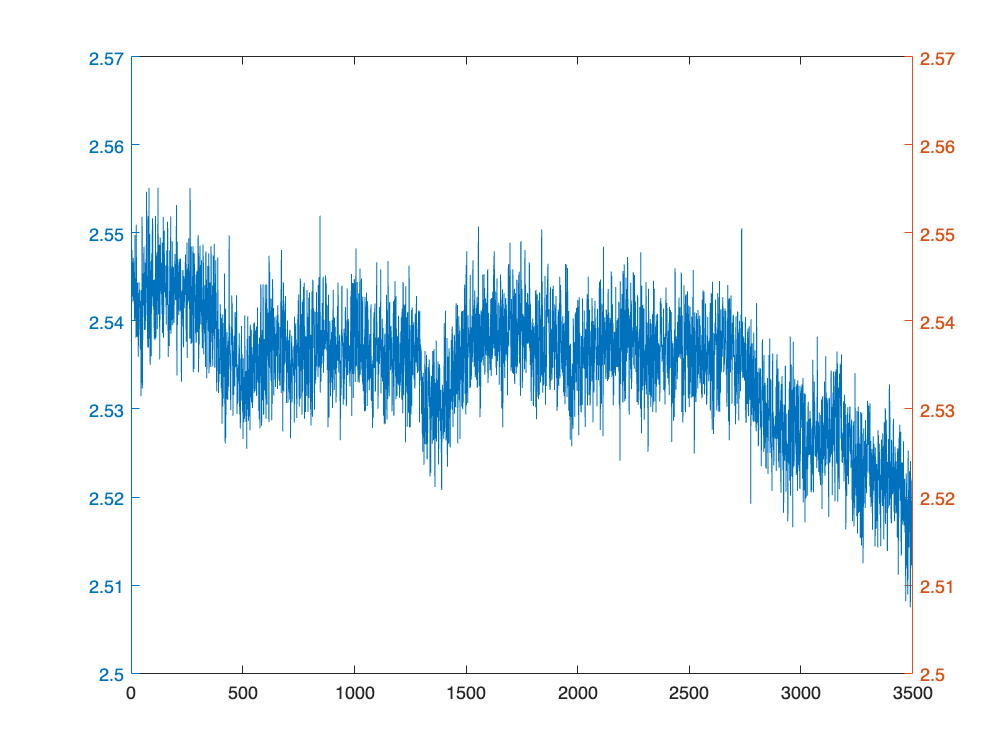

i = 1;
filename_new=[analysis_name,num2str(i),FilePostFix, '.mat'];
load(filename_new)
eval(['tau_', mouse, '_new = tau_empTrunc;'])

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

filename_old=[analysis_name,num2str(i),'_20230414','.mat'];
load(filename_old)
eval(['tau_', mouse, '_old = tau_empTrunc;'])

figure
yyaxis left
eval(['plot(tau_', mouse, '_old)'])
ylim([2.5 2.57])
yyaxis right
eval(['plot(tau_', mouse, '_new)'])
ylim([2.5 2.57])

i = 1;
filename_new=[analysis_name,num2str(i),FilePostFix, '.mat'];
load(filename_new)
eval(['tau_', mouse, '_new = tau_empTrunc;'])

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

filename_old=[analysis_name,num2str(i),'_20230414','.mat'];
load(filename_old)
eval(['tau_', mouse, '_old = tau_empTrunc;'])

figure
yyaxis left
eval(['plot(tau_', mouse, '_old)'])
ylim([2.5 2.57])
yyaxis right
eval(['plot(tau_', mouse, '_new)'])
ylim([2.5 2.57])

cd('/Volumes/PcSSDA/AChMut/20220208_109_AChMut_RvR_001')
ExperimentName='20220208_109_AChMut_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='109'

mouse = '109'


analysis_name=[ExperimentName,'_analysis_'];

global PeakGeneralization PostPeakChannels

PeakGeneralization = 2; % 'PeakGeneralization' method. 0, no peak channel generalization; 1, find peak for individual histogram; 2, set a certain peak.
PostPeakChannels = 85;

background_all = zeros(1,3);

for i = 1:3
    SpcFileLoad = load([ExperimentName, 'FLIM00', num2str(i), '.mat']);
    background_all(i) = sum(SpcFileLoad.spcSave.lifetimes{1})
end

background_all =    518     0     0


background_all =    518   499     0


background_all =    518   499   545



global backcorr BackGroundCorrection

backcorr = round((mean(background_all))/256)

backcorr = 2


BackGroundCorrection = 1;


i = 1;
filename_new=[analysis_name,num2str(i),'_20230414', '.mat'];
load(filename_new)

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

PeakChannelSet = find(histogram_mean == max(histogram_mean))

PeakChannelSet = 42


global PeakChannelSet


FLP_analysis_script

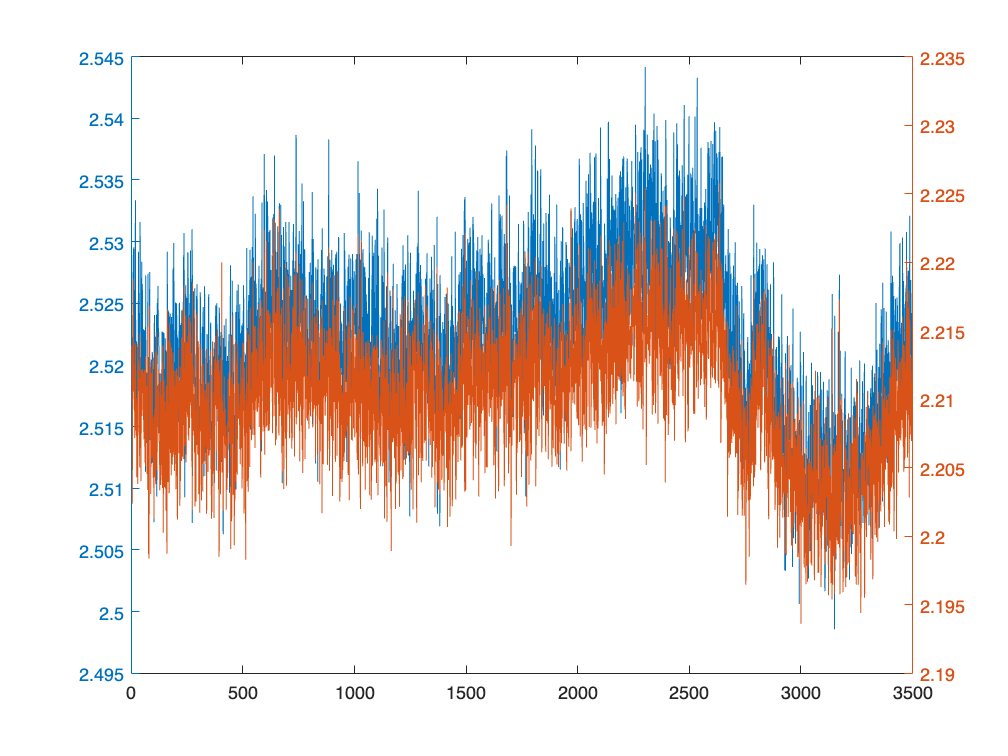

i = 1;
filename_new=[analysis_name,num2str(i),FilePostFix, '.mat'];
load(filename_new)
eval(['tau_', mouse, '_new = tau_empTrunc;'])

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

filename_old=[analysis_name,num2str(i),'_20230414','.mat'];
load(filename_old)
eval(['tau_', mouse, '_old = tau_empTrunc;'])

figure
yyaxis left
eval(['plot(tau_', mouse, '_old)'])
% ylim([2.5 2.57])
yyaxis right
eval(['plot(tau_', mouse, '_new)'])

% ylim([2.5 2.57])

cd('/Volumes/PcSSDA/AChMut/20220714_PM28_123_AChmut_RvR_001')
ExperimentName='20220714_PM28_123_AChmut_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='123'

mouse = '123'


analysis_name=[ExperimentName,'_analysis_'];

global PeakGeneralization PostPeakChannels

PeakGeneralization = 2; % 'PeakGeneralization' method. 0, no peak channel generalization; 1, find peak for individual histogram; 2, set a certain peak.
PostPeakChannels = 85;

background_all = zeros(1,3);

for i = 1:3
    SpcFileLoad = load([ExperimentName, 'FLIM00', num2str(i), '.mat']);
    background_all(i) = sum(SpcFileLoad.spcSave.lifetimes{1})
end

background_all =         1124           0           0


background_all =         1124        1142           0


background_all =         1124        1142        1138



global backcorr BackGroundCorrection

backcorr = round((mean(background_all))/256)

backcorr = 4


BackGroundCorrection = 1;


i = 1;
filename_new=[analysis_name,num2str(i),'_20230414', '.mat'];
load(filename_new)

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

PeakChannelSet = find(histogram_mean == max(histogram_mean))

PeakChannelSet = 43


global PeakChannelSet


FLP_analysis_script

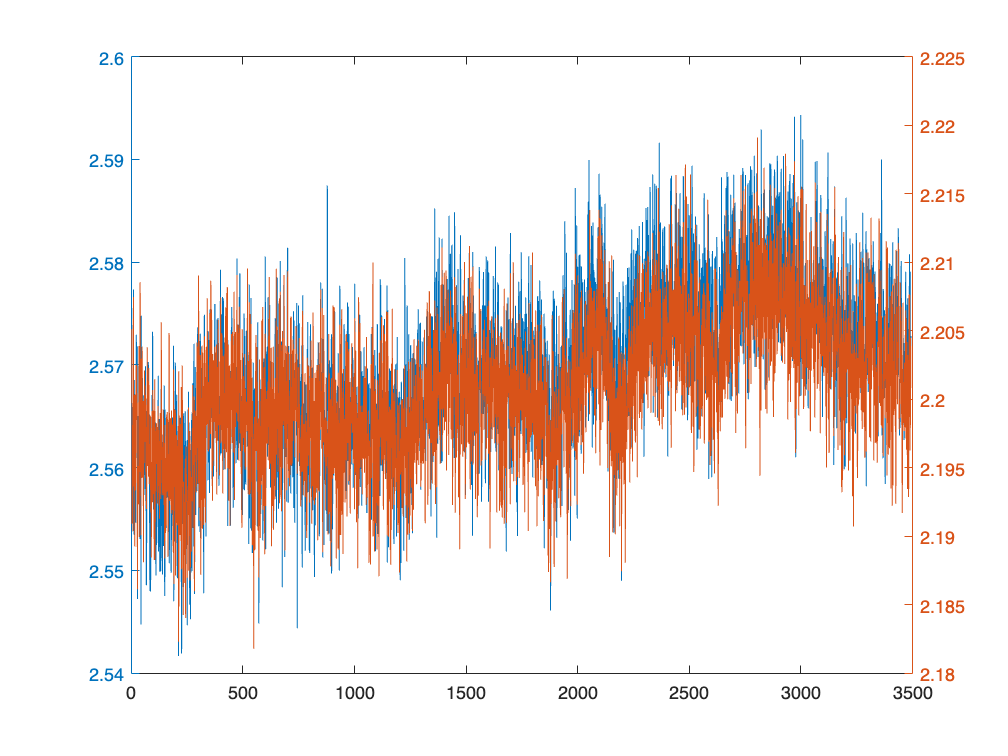

i = 1;
filename_new=[analysis_name,num2str(i),FilePostFix, '.mat'];
load(filename_new)
eval(['tau_', mouse, '_new = tau_empTrunc;'])

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

filename_old=[analysis_name,num2str(i),'_20230414','.mat'];
load(filename_old)
eval(['tau_', mouse, '_old = tau_empTrunc;'])

figure
yyaxis left
eval(['plot(tau_', mouse, '_old)'])
% ylim([2.5 2.57])
yyaxis right
eval(['plot(tau_', mouse, '_new)'])

% ylim([2.5 2.57])

cd('/Volumes/PcSSDA/AChMut/20220714_PM29_111_AChmut_RvR_002')
ExperimentName='20220714_PM29_111_AChmut_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='111'

mouse = '111'


analysis_name=[ExperimentName,'_analysis_'];

analysis_name=[ExperimentName,'_analysis_'];

global PeakGeneralization PostPeakChannels

PeakGeneralization = 2; % 'PeakGeneralization' method. 0, no peak channel generalization; 1, find peak for individual histogram; 2, set a certain peak.
PostPeakChannels = 85;

background_all = zeros(1,3);

for i = 1:3
    SpcFileLoad = load([ExperimentName, 'FLIM00', num2str(i), '.mat']);
    background_all(i) = sum(SpcFileLoad.spcSave.lifetimes{1})
end

background_all =         1226           0           0


background_all =         1226        1148           0


background_all =         1226        1148        1228



global backcorr BackGroundCorrection

backcorr = round((mean(background_all))/256)

backcorr = 5


BackGroundCorrection = 1;


i = 1;
filename_new=[analysis_name,num2str(i),'_20230414', '.mat'];
load(filename_new)

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

PeakChannelSet = find(histogram_mean == max(histogram_mean))

PeakChannelSet = 42


global PeakChannelSet


FLP_analysis_script

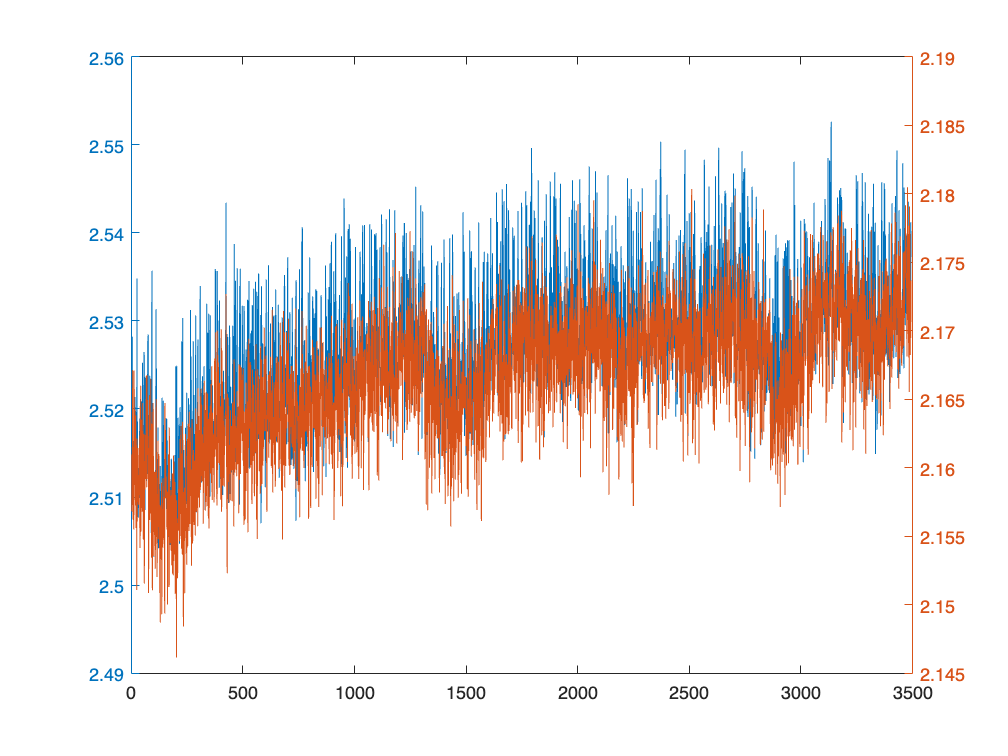

i = 1;
filename_new=[analysis_name,num2str(i),FilePostFix, '.mat'];
load(filename_new)
eval(['tau_', mouse, '_new = tau_empTrunc;'])

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

filename_old=[analysis_name,num2str(i),'_20230414','.mat'];
load(filename_old)
eval(['tau_', mouse, '_old = tau_empTrunc;'])

figure
yyaxis left
eval(['plot(tau_', mouse, '_old)'])
% ylim([2.5 2.57])
yyaxis right
eval(['plot(tau_', mouse, '_new)'])

% ylim([2.5 2.57])

mouse_all = {'112', '109', '111', '123'}

mouse_all = 1×4 cell array
    {'112'}    {'109'}    {'111'}    {'123'}


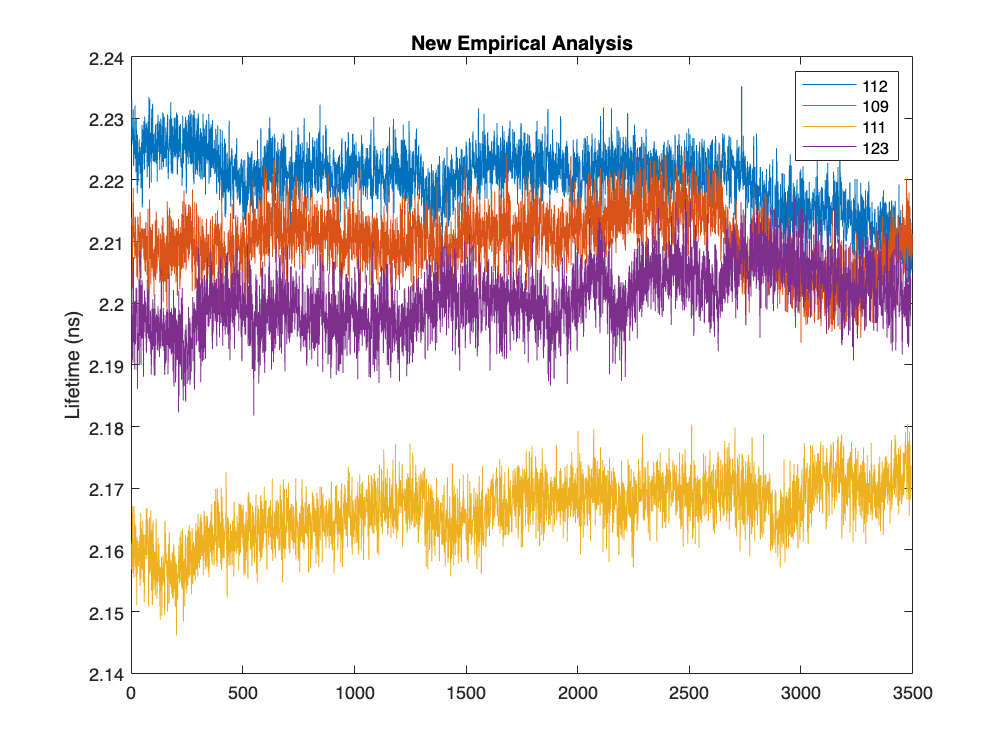


figure
for i = 1:4
    eval(['plot(tau_', mouse_all{i}, '_new)'])
    hold on
end
legend(mouse_all)
title('New Empirical Analysis')
% ylim([2.48 2.68])
ylabel('Lifetime (ns)')

hold off

mouse_all = {'112', '109', '111', '123'}

mouse_all = 1×4 cell array
    {'112'}    {'109'}    {'111'}    {'123'}


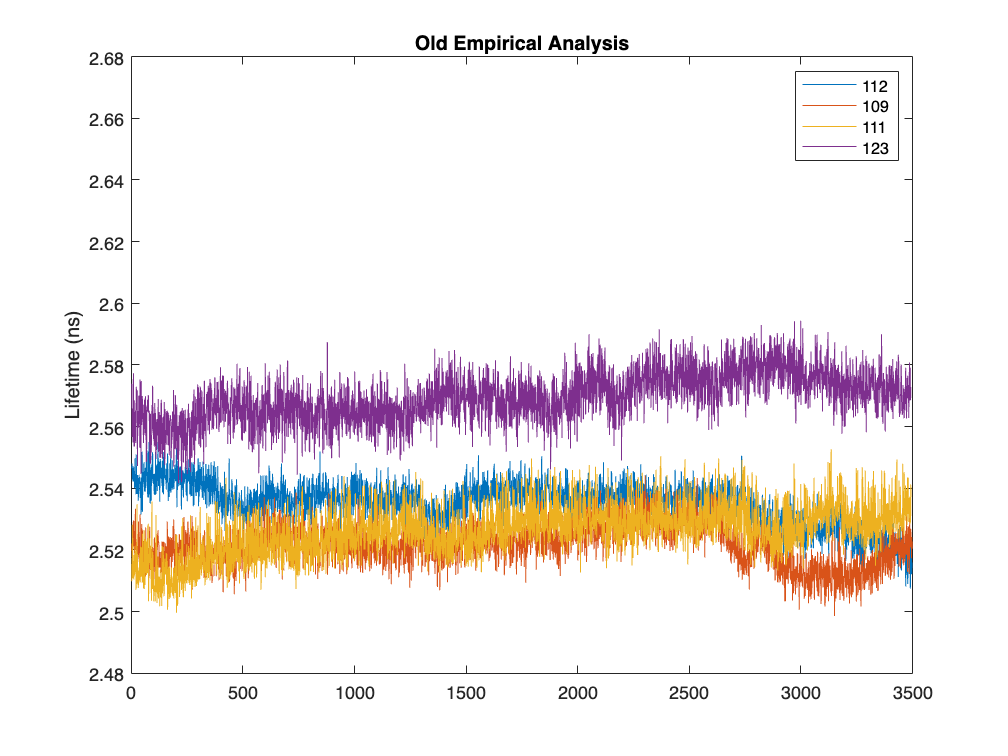


figure
for i = 1:4
    eval(['plot(tau_', mouse_all{i}, '_old)'])
    hold on
end

legend(mouse_all)
title('Old Empirical Analysis')
ylim([2.48 2.68])
ylabel('Lifetime (ns)')

hold off

mouse_all = {'112', '109', '111', '123'}

mouse_all = 1×4 cell array
    {'112'}    {'109'}    {'111'}    {'123'}


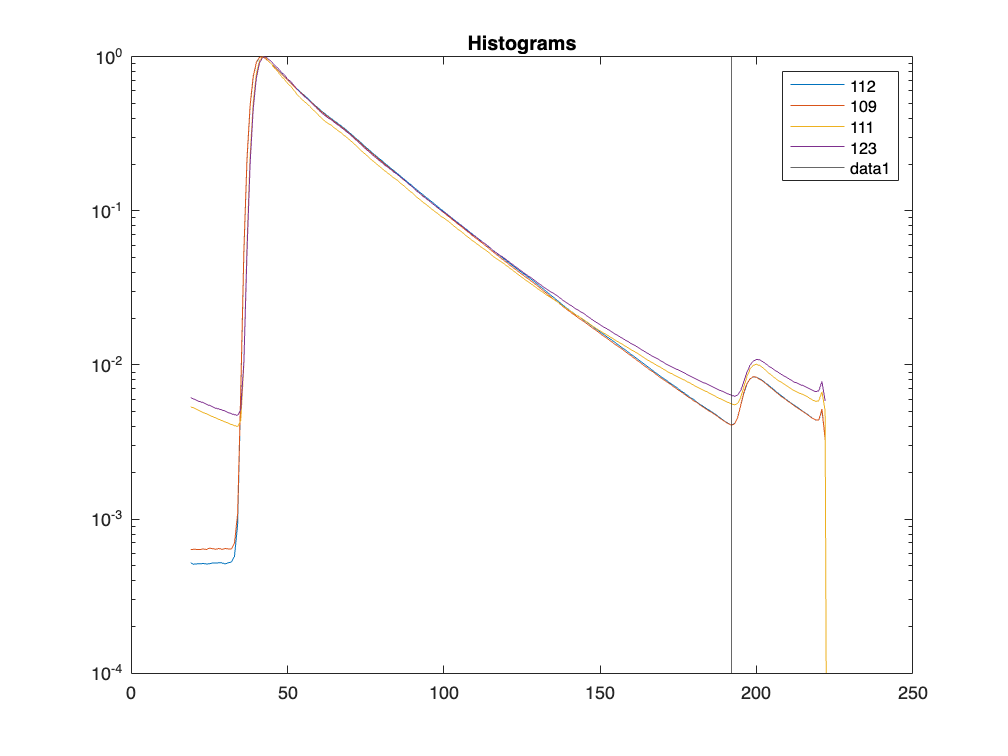


figure
for i = 1:4
    eval(['semilogy(histogram_mean_', mouse_all{i}, ')'])
    hold on
end

legend(mouse_all)
title('Histograms')
ylim([0.0001 1])
xline([192])

hold off

Different way of using the background term:

% FilePostFix = '_20230414_backcorr_2';

% cd('/Volumes/PcSSDA/AChMut/20220208_112_8_AChMut_RvR_001')
% ExperimentName='20220208_112_8_AChMut_RvR_001'; % Give a specific name to this experiment or this analysis
% FirstAcq=7;
% number_of_acq = 1;
% mouse='112'
% 
% analysis_name=[ExperimentName,'_analysis_'];
% 
% global PeakGeneralization PostPeakChannels
% 
% PeakGeneralization = 2; % 'PeakGeneralization' method. 0, no peak channel generalization; 1, find peak for individual histogram; 2, set a certain peak.
% PostPeakChannels = 150;

% global backcorr BackGroundCorrection
% BackGroundCorrection = 1;
% 
% i = 1;
% filename_new=[analysis_name,num2str(i),'_20230414', '.mat'];
% load(filename_new)
% 
% histogram_normalization = lifetime_histograms./max(lifetime_histograms);
% histogram_mean = mean(histogram_normalization');
% eval(['histogram_mean_', mouse, '= histogram_mean;'])
% backcorr = mean(mean(lifetime_histograms(20:31, :)))
% 
% PeakChannelSet = find(histogram_mean == max(histogram_mean))
% 
% global PeakChannelSet
% 

% FLP_analysis_script

% i = 1;
% filename_new=[analysis_name,num2str(i),FilePostFix, '.mat'];
% load(filename_new)
% eval(['tau_', mouse, '_new = tau_empTrunc;'])
% 
% histogram_normalization = lifetime_histograms./max(lifetime_histograms);
% histogram_mean = mean(histogram_normalization');
% eval(['histogram_mean_', mouse, '= histogram_mean;'])
% 
% filename_old=[analysis_name,num2str(i),'_20230414','.mat'];
% load(filename_old)
% eval(['tau_', mouse, '_old = tau_empTrunc;'])
% 
% figure
% yyaxis left
% eval(['plot(tau_', mouse, '_old)'])
% ylim([2.5 2.57])
% yyaxis right
% eval(['plot(tau_', mouse, '_new)'])
% ylim([2.5 2.57])

% cd('/Volumes/PcSSDA/AChMut/20220208_109_AChMut_RvR_001')
% ExperimentName='20220208_109_AChMut_RvR_001'; % Give a specific name to this experiment or this analysis
% FirstAcq=7;
% number_of_acq = 1;
% mouse='109'
% 
% analysis_name=[ExperimentName,'_analysis_'];
% 
% global PeakGeneralization PostPeakChannels
% 
% PeakGeneralization = 2; % 'PeakGeneralization' method. 0, no peak channel generalization; 1, find peak for individual histogram; 2, set a certain peak.
% PostPeakChannels = 150;

% global backcorr BackGroundCorrection
% BackGroundCorrection = 1;
% 
% i = 1;
% filename_new=[analysis_name,num2str(i),'_20230414', '.mat'];
% load(filename_new)
% 
% histogram_normalization = lifetime_histograms./max(lifetime_histograms);
% histogram_mean = mean(histogram_normalization');
% eval(['histogram_mean_', mouse, '= histogram_mean;'])
% backcorr = mean(mean(lifetime_histograms(20:31, :)))
% 
% global PeakChannelSet
% PeakChannelSet = find(histogram_mean == max(histogram_mean))
% 

% FLP_analysis_script

% i = 1;
% filename_new=[analysis_name,num2str(i),FilePostFix, '.mat'];
% load(filename_new)
% eval(['tau_', mouse, '_new = tau_empTrunc;'])
% 
% histogram_normalization = lifetime_histograms./max(lifetime_histograms);
% histogram_mean = mean(histogram_normalization');
% eval(['histogram_mean_', mouse, '= histogram_mean;'])
% 
% filename_old=[analysis_name,num2str(i),'_20230414','.mat'];
% load(filename_old)
% eval(['tau_', mouse, '_old = tau_empTrunc;'])
% 
% figure
% yyaxis left
% eval(['plot(tau_', mouse, '_old)'])
% % ylim([2.5 2.57])
% yyaxis right
% eval(['plot(tau_', mouse, '_new)'])
% % ylim([2.5 2.57])

% cd('/Volumes/PcSSDA/AChMut/20220714_PM28_123_AChmut_RvR_001')
% ExperimentName='20220714_PM28_123_AChmut_RvR_001'; % Give a specific name to this experiment or this analysis
% FirstAcq=7;
% number_of_acq = 1;
% mouse='123'
% 
% analysis_name=[ExperimentName,'_analysis_'];
% 
% global PeakGeneralization PostPeakChannels
% 
% PeakGeneralization = 2; % 'PeakGeneralization' method. 0, no peak channel generalization; 1, find peak for individual histogram; 2, set a certain peak.
% PostPeakChannels = 150;

% global backcorr BackGroundCorrection
% BackGroundCorrection = 1;
% 
% i = 1;
% filename_new=[analysis_name,num2str(i),'_20230414', '.mat'];
% load(filename_new)
% 
% histogram_normalization = lifetime_histograms./max(lifetime_histograms);
% histogram_mean = mean(histogram_normalization');
% eval(['histogram_mean_', mouse, '= histogram_mean;'])
% backcorr = mean(mean(lifetime_histograms(20:31, :)))
% 
% global PeakChannelSet
% PeakChannelSet = find(histogram_mean == max(histogram_mean))
% 

% FLP_analysis_script

% i = 1;
% filename_new=[analysis_name,num2str(i),FilePostFix, '.mat'];
% load(filename_new)
% eval(['tau_', mouse, '_new = tau_empTrunc;'])
% 
% histogram_normalization = lifetime_histograms./max(lifetime_histograms);
% histogram_mean = mean(histogram_normalization');
% eval(['histogram_mean_', mouse, '= histogram_mean;'])
% 
% filename_old=[analysis_name,num2str(i),'_20230414','.mat'];
% load(filename_old)
% eval(['tau_', mouse, '_old = tau_empTrunc;'])
% 
% figure
% yyaxis left
% eval(['plot(tau_', mouse, '_old)'])
% % ylim([2.5 2.57])
% yyaxis right
% eval(['plot(tau_', mouse, '_new)'])
% % ylim([2.5 2.57])

% cd('/Volumes/PcSSDA/AChMut/20220714_PM29_111_AChmut_RvR_002')
% ExperimentName='20220714_PM29_111_AChmut_RvR_002'; % Give a specific name to this experiment or this analysis
% FirstAcq=7;
% number_of_acq = 1;
% mouse='111'
% 
% analysis_name=[ExperimentName,'_analysis_'];
% 
% analysis_name=[ExperimentName,'_analysis_'];
% 
% global PeakGeneralization PostPeakChannels
% 
% PeakGeneralization = 2; % 'PeakGeneralization' method. 0, no peak channel generalization; 1, find peak for individual histogram; 2, set a certain peak.
% PostPeakChannels = 150;

% global backcorr BackGroundCorrection
% BackGroundCorrection = 1;
% 
% i = 1;
% filename_new=[analysis_name,num2str(i),'_20230414', '.mat'];
% load(filename_new)
% 
% histogram_normalization = lifetime_histograms./max(lifetime_histograms);
% histogram_mean = mean(histogram_normalization');
% eval(['histogram_mean_', mouse, '= histogram_mean;'])
% backcorr = mean(mean(lifetime_histograms(20:31, :)))
% 
% global PeakChannelSet
% PeakChannelSet = find(histogram_mean == max(histogram_mean))
% 

% FLP_analysis_script

% i = 1;
% filename_new=[analysis_name,num2str(i),FilePostFix, '.mat'];
% load(filename_new)
% eval(['tau_', mouse, '_new = tau_empTrunc;'])
% 
% histogram_normalization = lifetime_histograms./max(lifetime_histograms);
% histogram_mean = mean(histogram_normalization');
% eval(['histogram_mean_', mouse, '= histogram_mean;'])
% 
% filename_old=[analysis_name,num2str(i),'_20230414','.mat'];
% load(filename_old)
% eval(['tau_', mouse, '_old = tau_empTrunc;'])
% 
% figure
% yyaxis left
% eval(['plot(tau_', mouse, '_old)'])
% % ylim([2.5 2.57])
% yyaxis right
% eval(['plot(tau_', mouse, '_new)'])
% % ylim([2.5 2.57])

% mouse_all = {'112', '109', '111', '123'}
% 
% figure
% for i = 1:4
%     eval(['plot(tau_', mouse_all{i}, '_new)'])
%     hold on
% end
% legend(mouse_all)
% title('New Empirical Analysis')
% % ylim([2.48 2.68])
% ylabel('Lifetime (ns)')
% 
% hold off

% mouse_all = {'112', '109', '111', '123'}
% 
% figure
% for i = 1:4
%     eval(['plot(tau_', mouse_all{i}, '_old)'])
%     hold on
% end
% 
% legend(mouse_all)
% title('Old Empirical Analysis')
% ylim([2.48 2.68])
% ylabel('Lifetime (ns)')
% 
% hold off

% histogram_mean_123_shifted = zeros(1,256);
% 

% mouse_all = {'112', '109', '111', '123'}
% Colors = {'b', 'g', 'k', 'r'}
% 
% figure
% for i = 1:4
%     eval(['semilogy(histogram_mean_', mouse_all{i},'Color', Colors{i}, ')'])
%     hold on
% end
% 
% legend(mouse_all)
% title('Histograms')
% ylim([0.0001 1])
% xline([192])
% 
% hold off

% i = 1;
% figure
% semilogy(histogram_mean_112, 'Color', 'b', 'LineWidth',2)
% % i = i+1
% % hold on
% % semilogy(histogram_mean_109, 'Color', Colors{i}, 'LineWidth',2)
% i = i+1
% hold on
% semilogy(histogram_mean_backcorr, 'Color','k', 'LineWidth',2)
% i = i+1
% hold on
% semilogy(histogram_resting_mean, 'Color', 'r', 'LineWidth',2)
% hold on
% semilogy(histogram_running_mean, 'Color', 'g', 'LineWidth',2)
% legend('112Mut', '123Mut', 'resting', 'running')

% 
% lifetime_histograms_backcorr = lifetime_histograms - backcorr;
% lifetime_histograms_backcorr(find(lifetime_histograms_backcorr<0)) = 0;
% histogram_normalization_backcorr = lifetime_histograms_backcorr./max(lifetime_histograms_backcorr);
% histogram_mean_backcorr = mean(histogram_normalization_backcorr');